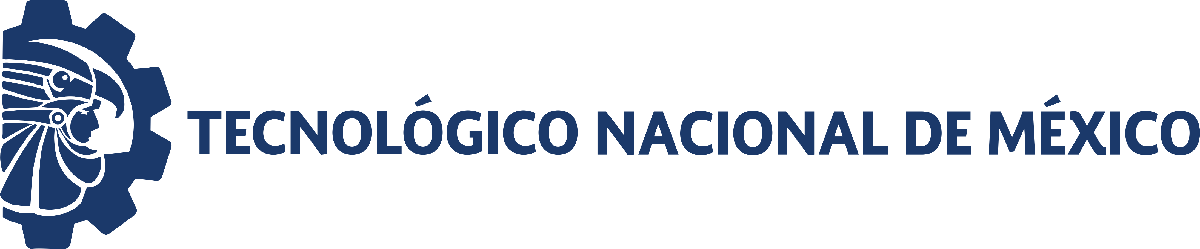                                 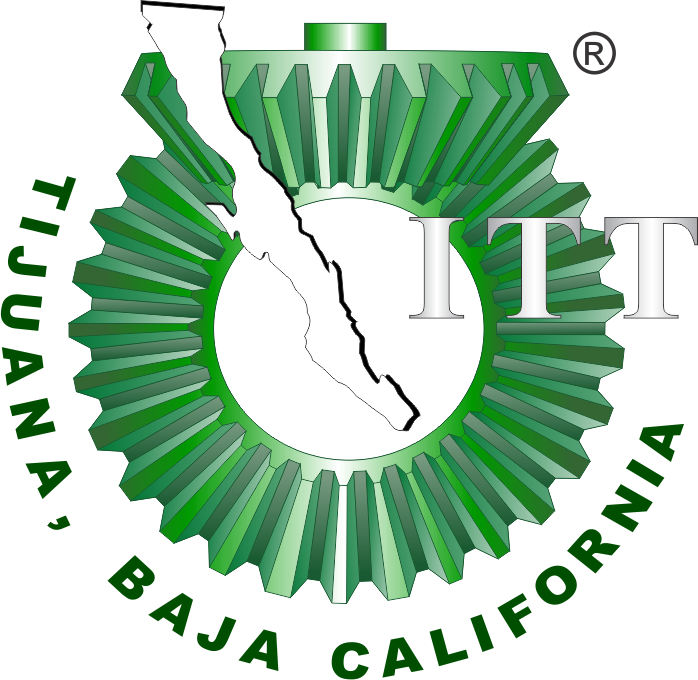

# Práctica 5: Analisis de Sistemas Biologicos

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

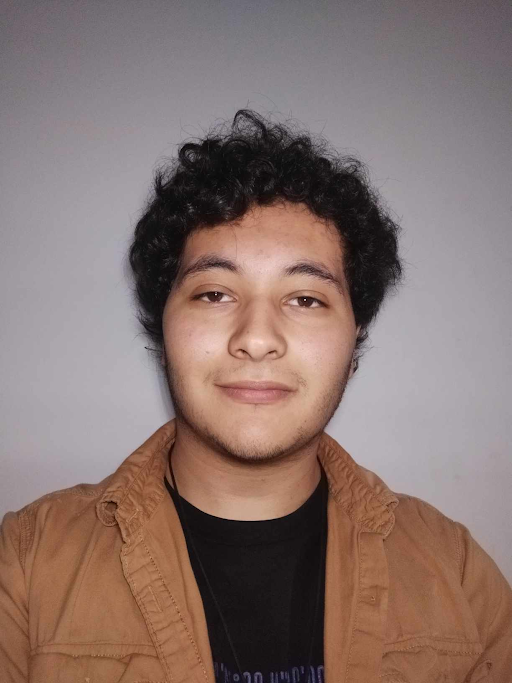

Nombre del alumno: **Hector Andres Fernandez Esquivel**

Número de control: **21212153**

Correo institucional: **l21212153@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

### Simulation data

### Chaotic attractor [normalized]

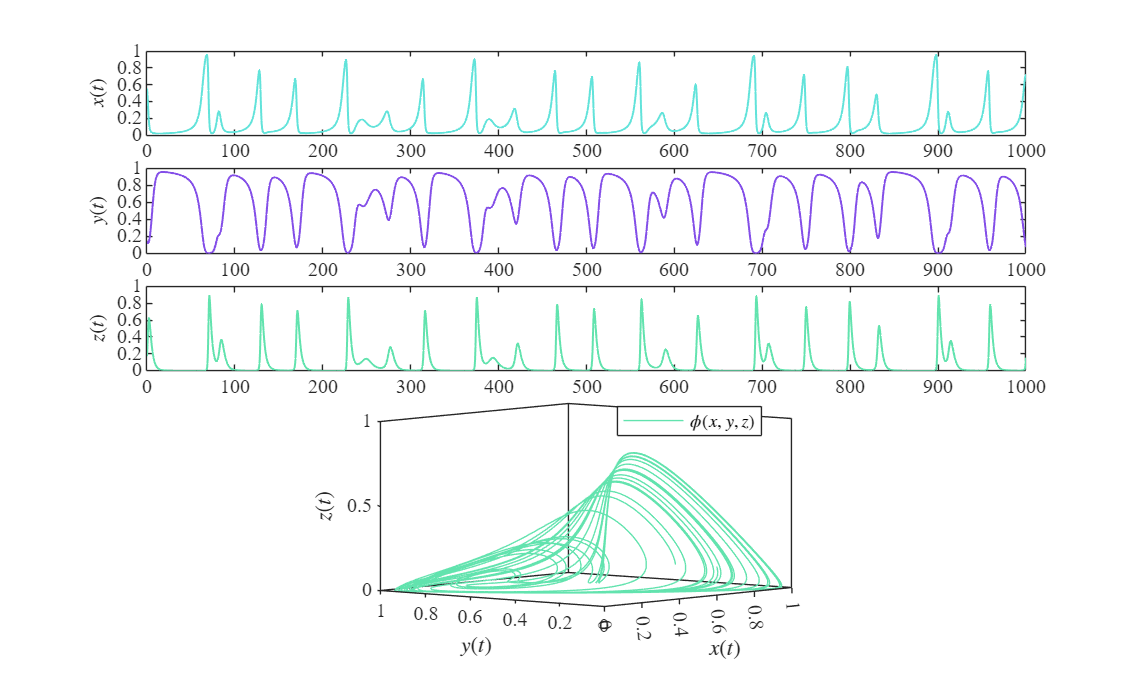

clc; clear; close all; warning('off','all')
P = [1,1,2.5,0.6,1,1.5,3,0.3,0.4];
[t,x,y,z] = System(0.555,0.148,0.172,P,1,0,1E-2,1000);
plotEDOs(t,x,y,z)
exportgraphics(gcf,'Chaotic attractor.pdf','ContentType','vector')

### Periodic orbit [normalized]

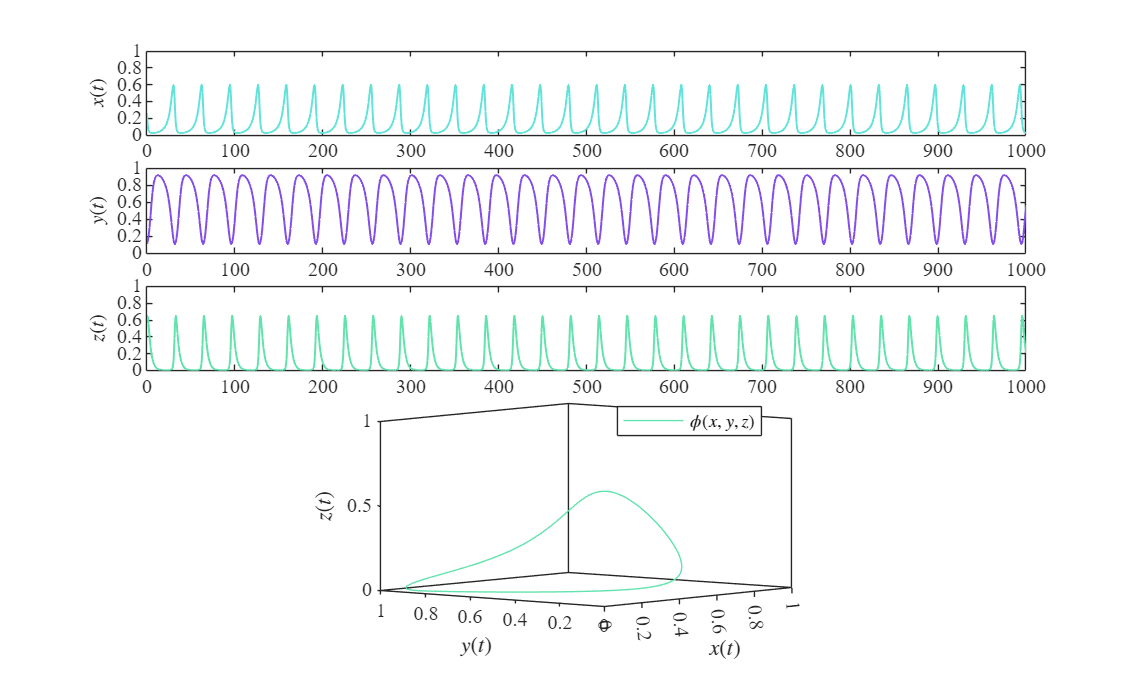

P = [1,1,2.5,0.6,1,1.5,3,0.3,0.4];
[t,x,y,z] = System(0.254781,0.115167,0.600527,P,0.9,0,1E-2,1000);
plotEDOs(t,x,y,z)
exportgraphics(gcf,'Periodic Orbit.pdf','ContentType','vector')

### Limit cycle internal [normalized]

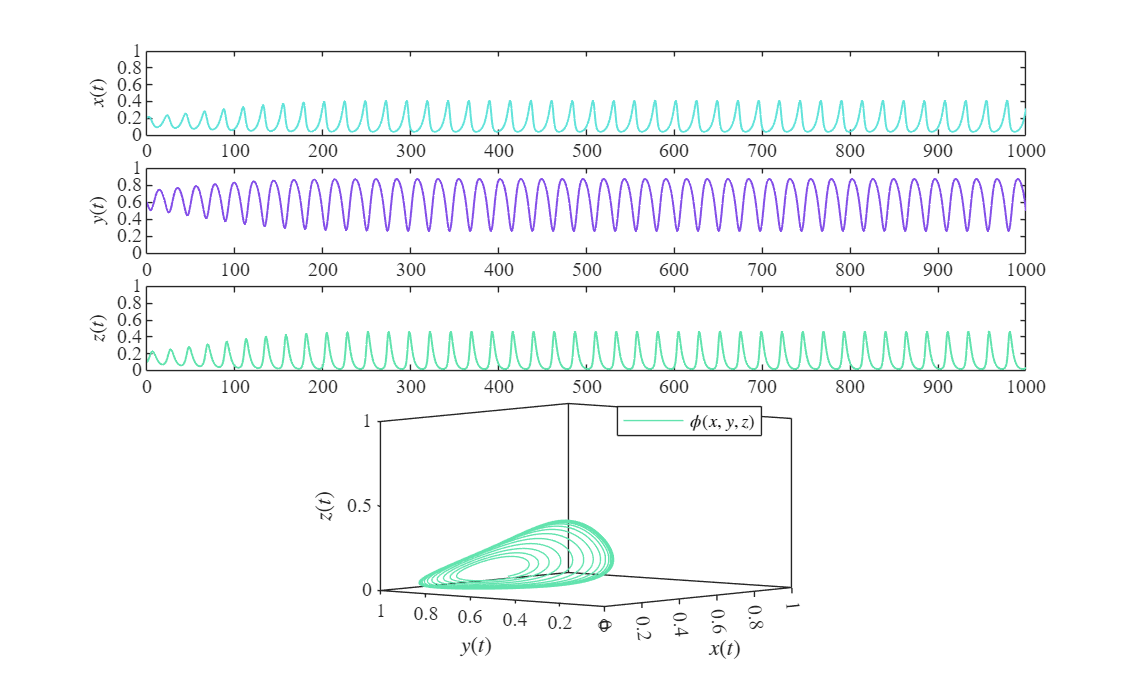

P = [1,1,2.5,0.6,1,1.5,3,0.3,0.4];
[t,x,y,z] = System(0.2,0.6,0.1,P,0.8,0,1E-2,1000);
plotEDOs(t,x,y,z)
exportgraphics(gcf,'limit cycle internal ic normalized.pdf','ContentType','vector')

### Limit cycle external [normalized]

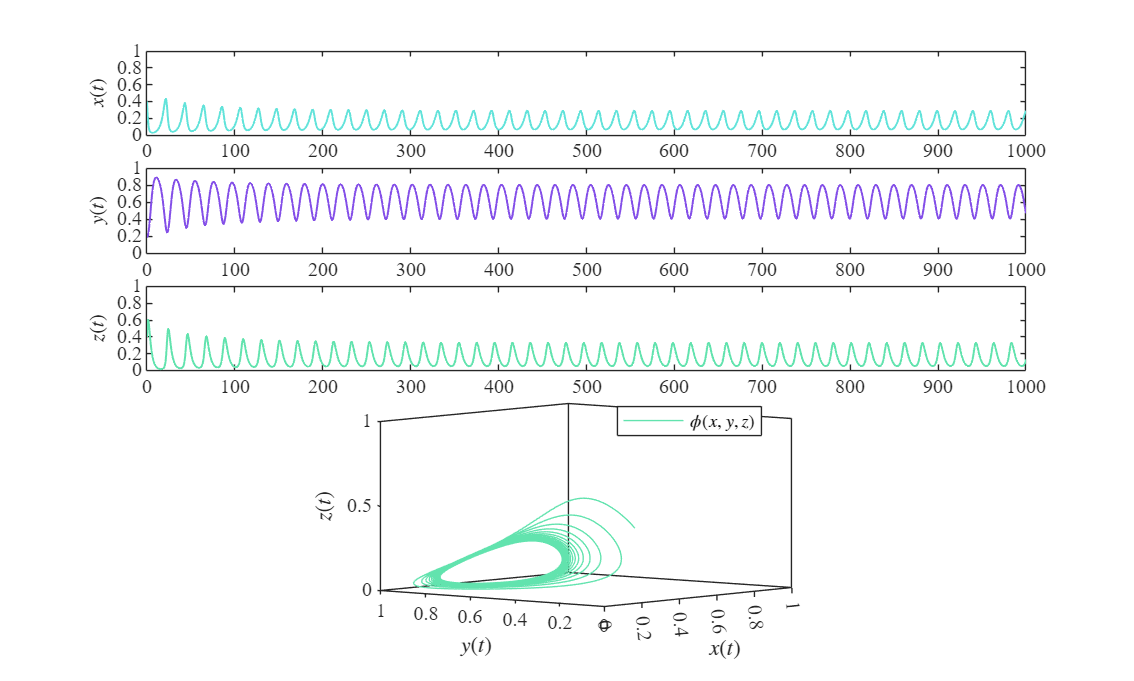

P = [1,1,2.5,0.6,1,1.5,3,0.3,0.4];
[t,x,y,z] = System(0.4,0.2,0.4,P,0.75,0,1E-2,1000);
plotEDOs(t,x,y,z)
exportgraphics(gcf,'limit cycle external ic normalized.pdf','ContentType','vector')

### Equilibrium point [normalized]

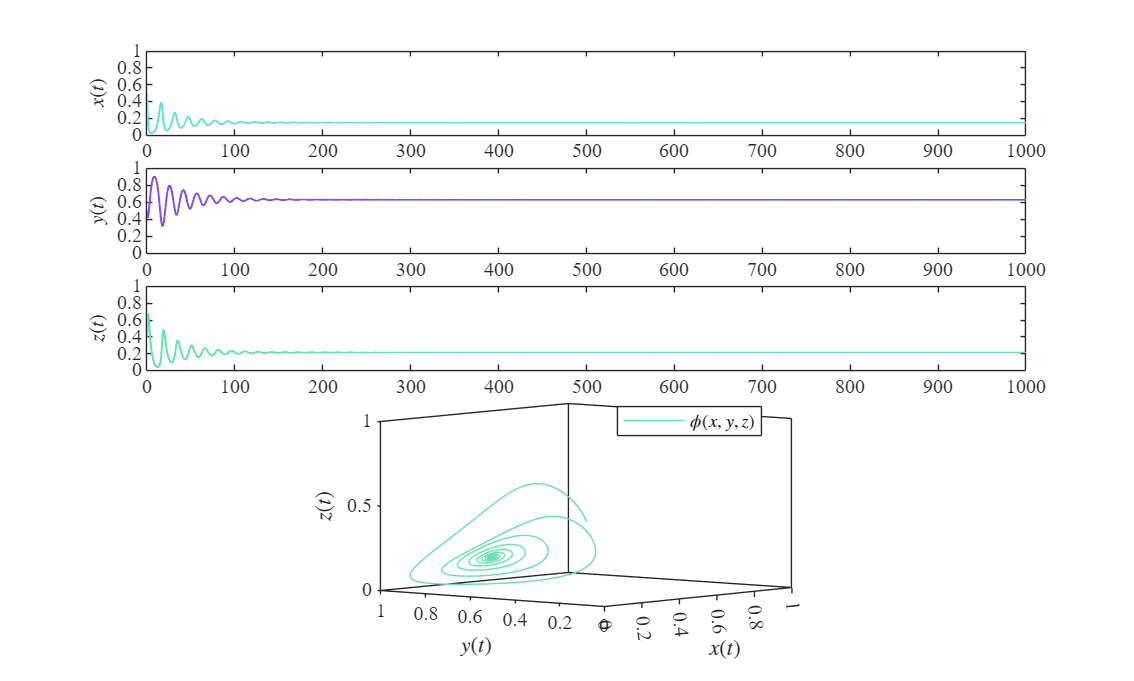

P = [1,1,2.5,0.6,1,1.5,3,0.3,0.4];
[t,x,y,z] = System(0.5,0.5,0.4,P,0.5,0,1E-2,1000);
plotEDOs(t,x,y,z)
exportgraphics(gcf,'Equilibrium point normalized.pdf','ContentType','vector')

### Limited cycle internal [non-normalized]

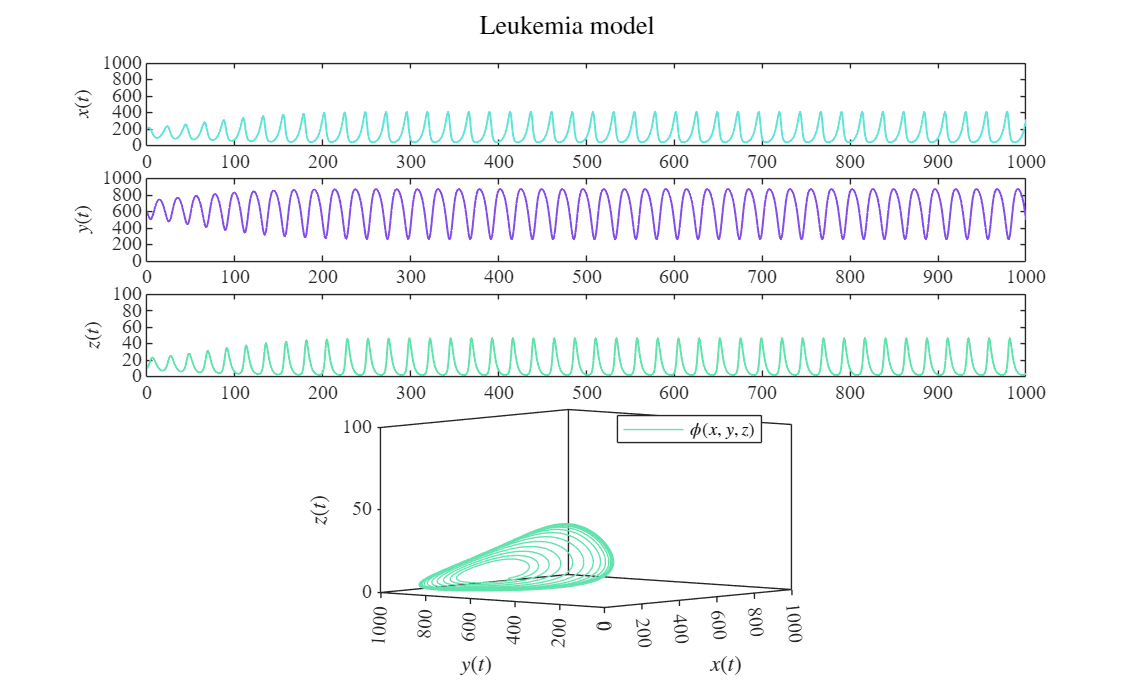

xmax = 1E3; ymax = 1E3; zmax = 1E2;
%b1 = 1/xmax; a12 = 0.8/ymax; a13 = 2.5/zmax;
%b2 = 1/ymax; a21 = 1.5/xmax;
%r3 = 3/xmax; a31 = 0.3/xmax;
%r1 = 1; r2 = 0.6; d3 = 0.4;
%rhoi = 0 %dt = 1E-2;

P = [1,1/xmax,2.5/zmax,0.6,1/ymax,1.5/xmax,3/xmax,0.3/xmax,0.4];
[t,x,y,z] = System(0.2*xmax,0.6*ymax,0.1*zmax,P,0.8/ymax,0,1E-2,1000);
plotEDOsn(t,x,y,z)
ttl = 'Leukemia model'; sgtitle(ttl,'Interpreter','latex')
exportgraphics(gcf,'limit cycle internal ic non-normalized.pdf','ContentType','vector')

## Equilibrium points and Jacobian matrix

clear
syms x y z r1 b1 a12 a13 r2 b2 a21 r3 a31 d3 rhoi

dx = r1*x*(1 - b1*x) - a12*x*y - a13*x*z;
dy = r2*y*(1 - b2*y) - a21*x*y;
dz = (r3 - a31)*x*z - d3*z + rhoi;
J = jacobian([dx,dy,dz],[x,y,z]); disp(J)

$$\left(\begin{array}{ccc} -a_{12}\,y-a_{13}\,z-r_{1}\,\left(b_{1}\,x-1\right)-b_{1}\,r_{1}\,x & -a_{12}\,x & -a_{13}\,x\\ -a_{21}\,y & -a_{21}\,x-r_{2}\,\left(b_{2}\,y-1\right)-b_{2}\,r_{2}\,y & 0\\ -z\,\left(a_{31}-r_{3}\right) & 0 & -d_{3}-x\,\left(a_{31}-r_{3}\right) \end{array}\right)$$


dx = r1*x*(1 - b1*x) - a12*x*y - a13*x*z == 0;
dy = r2*y*(1 - b2*y) - a21*x*y == 0;
dz = (r3 - a31)*x*z - d3*z + rhoi == 0;
equilibria = solve([dx,dy,dz],[x,y,z]);
for i = 1:6
    xe(i,1) = simplify(equilibria.x(i));
    ye(i,1) = simplify(equilibria.y(i));
    ze(i,1) = simplify(equilibria.z(i));

    fprintf(['Equilibrium ponts of the system: ', num2str(i), '\n'])
    fprintf(['x',num2str(i), ' = ', char(xe(i,1))]);
    fprintf(['y',num2str(i), ' = ', char(ye(i,1))]);
    fprintf(['z',num2str(i), ' = ', char(ze(i,1))]);
end

Equilibrium ponts of the system: 1


x1 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3))

y1 = 0

z1 = (a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3))

Equilibrium ponts of the system: 2


x2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3))

y2 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3))

z2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3))

Equilibrium ponts of the system: 3


x3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3))

y3 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3))

z3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3))

Equilibrium ponts of the system: 4


x4 = 0

y4 = 1/b2

z4 = rhoi/d3

Equilibrium ponts of the system: 5


x5 = -(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3))

y5 = 0

z5 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3))

Equilibrium ponts of the system: 6


x6 = 0

y6 = 0

z6 = rhoi/d3

### Equilibrium points with no treatment

clear
a12i = 0.8;
r1 = 1; b1 = 1; a12 = 1; a13 = 2.5;
r2 = 0.6; b2 = 1; a21 = 1.5;
r3 = 3; a31 = 0.3; d3 = 0.4;
rhoi = 0;
for i = 1:numel(a12i)
    a12 = a12i(i);
    x1 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y1 = 0;
    z1 = (a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y2 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y3 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x4 = 0;
    y4 = 1/b2;
    z4 = rhoi/d3;

    x5 = -(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y5 = 0;
    z5 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x6 = 0;
    y6 = 0;
    z6 = rhoi/d3;

    x = [x1; x2; x3; x4; x5; x6]; y = [y1; y2; y3; y4; y5; y6]; z = [z1; z2; z3; z4; z5; z6];

    for i = 1:numel(x)
        J = [- a12*y(i) - a13*z(i) - r1*(b1*x(i) - 1) - b1*r1*x(i),         -a12*x(i),          -a13*x(i); 
                -a21*y(i), - a21*x(i) - r2*(b2*y(i) - 1) - b2*r2*y(i), 0,;
                    -z(i)*(a31 - r3), 0, - d3 - x(i)*(a31 - r3)];

        L(i,:) = eig(J);
    end
    Lambda1 = L(:,1); Lambda2 = L(:,2); Lambda3 = L(:,3);

    Eqs = array2table([x, y, z, Lambda1, Lambda2, Lambda3], 'VariableNames', {'x*','y*','z*', 'Lambda 1', 'Lambda 2', 'Lambda 3'});
    fprintf(['Equilibrium points with a12 = ',num2str(a12), '\n'])
    fprintf(['Treatment rhoi = ', num2str(rhoi), '\n'])
    disp(Eqs)
end

Equilibrium points with a12 = 0.8


Treatment rhoi = 0


      x*         y*           z*              Lambda 1              Lambda 2             Lambda 3    
    _______    _______    ___________    __________________    __________________    ________________

    0.14815          0        0.34074    -0.074074+0.57901i    -0.074074-0.57901i     0.37778+0i     
    0.14815    0.62963        0.13926     -0.54882+0i           0.011448+0.3094i     0.011448-0.3094i
       -0.2        1.5    -1.3706e-16        -0.35+0.23979i        -0.35-0.23979i       -0.94+0i     
          0          1              0         -0.6+0i                0.2+0i              -0.4+0i     
          1          0     2.4672e-17           -1+0i                2.3+0i              -0.9+0i     
          0          0              0         -0.4+0i                0.6+0i      

### Equilibrium with treatment

clear
a12i = 0.8;
r1 = 1; b1 = 1; a12 = 1; a13 = 2.5;
r2 = 0.6; b2 = 1; a21 = 1.5;
r3 = 3; a31 = 0.3; d3 = 0.4;
rhoi = 1.1*(d3*r1)/a13;
for i = 1:numel(a12i)
    a12 = a12i(i);
    x1 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y1 = 0;
    z1 = (a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y2 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y3 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x4 = 0;
    y4 = 1/b2;
    z4 = rhoi/d3;

    x5 = -(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y5 = 0;
    z5 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x6 = 0;
    y6 = 0;
    z6 = rhoi/d3;

    x = [x1; x2; x3; x4; x5; x6]; y = [y1; y2; y3; y4; y5; y6]; z = [z1; z2; z3; z4; z5; z6];

    for i = 1:numel(x)
        J = [- a12*y(i) - a13*z(i) - r1*(b1*x(i) - 1) - b1*r1*x(i),         -a12*x(i),          -a13*x(i); 
                -a21*y(i), - a21*x(i) - r2*(b2*y(i) - 1) - b2*r2*y(i), 0,;
                    -z(i)*(a31 - r3), 0, - d3 - x(i)*(a31 - r3)];

        L(i,:) = eig(J);
    end
    Lambda1 = L(:,1); Lambda2 = L(:,2); Lambda3 = L(:,3);

    Eqs = array2table([x, y, z, Lambda1, Lambda2, Lambda3], 'VariableNames', {'x*','y*','z*', 'Lambda 1', 'Lambda 2', 'Lambda 3'});
    fprintf(['Equilibrium points with a12 = ',num2str(a12), '\n'])
    fprintf(['Treatment rhoi = ', num2str(rhoi), '\n'])
    disp(Eqs)
end

Equilibrium points with a12 = 0.8


Treatment rhoi = 0.176


            x*                  y*                   z*                Lambda 1              Lambda 2             Lambda 3     
    __________________    _______________    __________________    _________________    __________________    _________________

    -0.012761+0i               0+0i             0.4051+0i          0.080522+0i          -0.50222+0i            0.61914+0i      
    -0.025926+0.36423i    1.0648-0.91057i      0.06963+0.14569i      0.5083+0.21042i    -0.99651+0.028787i    -0.59475+0.92632i
    -0.025926-0.36423i    1.0648+0.91057i      0.06963-0.14569i      0.5083-0.21042i    -0.99651-0.028787i    -0.59475-0.92632i
            0+0i               1+0i               0.44+0i              -0.4+0i              -0.6+0i               -0.9+0i      
       1.1609+0i           

## Chaotic attractor [normalized]

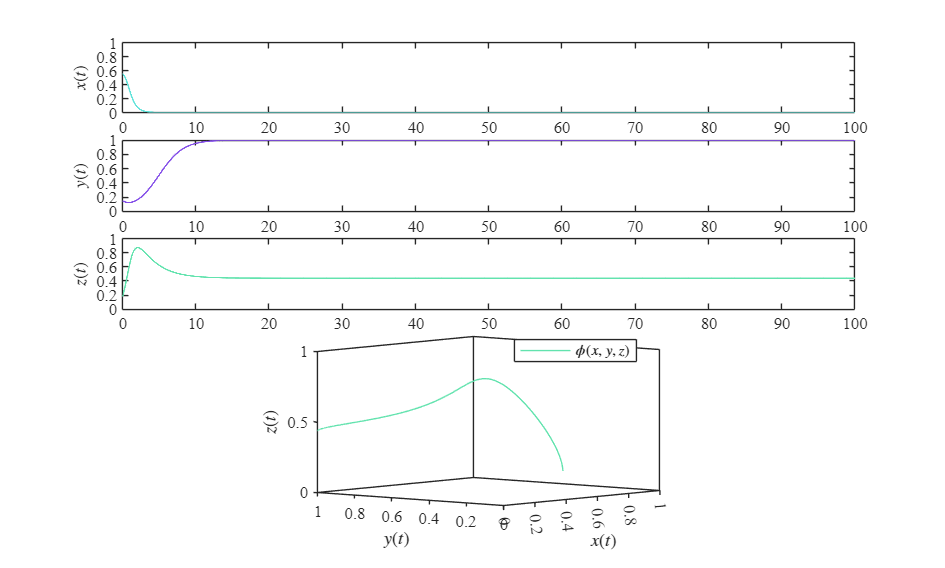

r1 = 1; b1 = 1; a12 = 1; a13 = 2.5;
r2 = 0.6; b2 = 1; a21 = 1.5;
r3 = 3; a31 = 0.3; d3 = 0.4;
P = [r1 b1 a13 r2 b2 a21 r3 a31 d3];
rhoi = 1.1*d3*r1/a13;
dt  = 1E-2;
x0 = 0.555; y0 = 0.148; z0 = 0.172;
tend = 100;
[t,x,y,z] = System(x0,y0,z0,P,a12,rhoi,dt,tend);
plotEDO10s(t,x,y,z); exportgraphics(gcf,'Chaotic attractor normalized rhoi.pdf','ContentType','vector')

## Limited cycle internal [non-normalized]

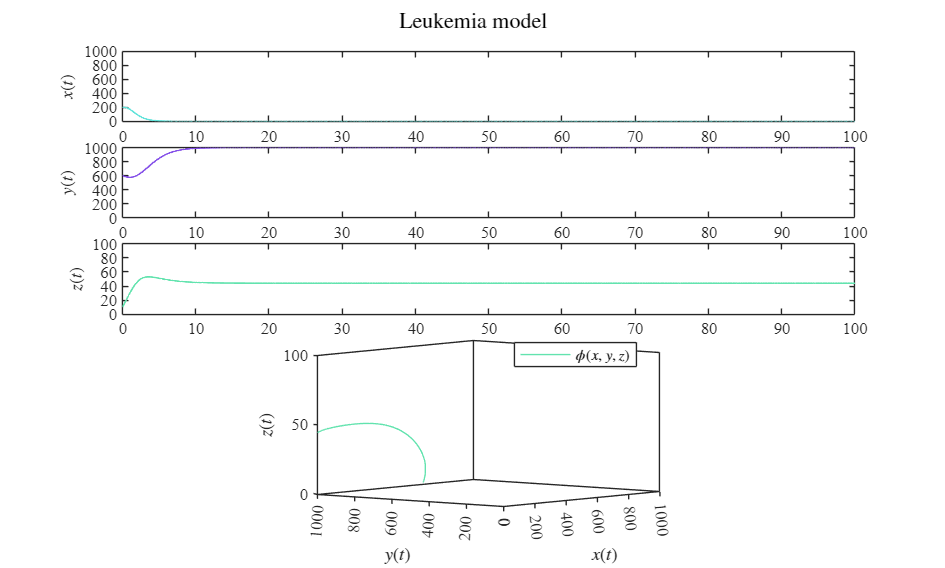

xmax = 1E3; ymax = 1E3; zmax = 1E2;
b1 = 1/xmax; a12 = 0.8/ymax; a13 = 2.5/zmax;
b2 = 1/ymax; a21 = 1.5/xmax;
r3 = 3/xmax; a31 = 0.3/xmax;
r1 = 1; r2 = 0.6; d3 = 0.4;
rhoi = 1.1*d3*r1/a13; 
dt = 1E-2;
x0 = 0.2*xmax; y0 = 0.6*xmax; z0 = 0.1*zmax;
tend = 1000;
P = [r1 b1 a13 r2 b2 a21 r3 a31 d3];
[t,x,y,z] = System(x0,y0,z0,P,a12,rhoi,dt,tend);
plotEDO10sn(t,x,y,z)
ttl = 'Leukemia model'; sgtitle(ttl,'Interpreter','latex')
exportgraphics(gcf,'limit cycle internal ic non-normalized rhoi.pdf','ContentType','vector')

## Functions

function [t,x,y,z] = System(x0,y0,z0,P,a12,rhoi,dt,tend)
    r1 = P(1);  b1 = P(2);  a13 = P(3);
    r2 = P(4);  b2 = P(5);  a21 = P(6);
    r3 = P(7);  a31 = P(8); d3 = P(9);

    t = (0:dt:tend)';
    n = round(tend/dt);
    x = zeros(n+1,1); x(1) = x0;
    y = zeros(n+1,1); y(1) = y0;
    z = zeros(n+1,1); z(1) = z0;

    for i = 1:n
        [fx,fy,fz] = f(x(i),y(i),z(i));
        xn = x(i) + fx*dt;
        yn = y(i) + fy*dt;
        zn = z(i) + fz*dt;

        [fxn,fyn,fzn] = f(xn,yn,zn);
        x(i+1) = x(i) + (fx + fxn)*dt/2;
        y(i+1) = y(i) + (fy + fyn)*dt/2;
        z(i+1) = z(i) + (fz + fzn)*dt/2;
    end

    function [dx, dy, dz] = f(x, y, z)
        dx = r1*x*(1-b1*x)-a12*x*y-a13*x*z;
        dy = r2*y*(1-b2*y)-a21*x*y;
        dz = (r3-a31)*x*z-d3*z+rhoi;
    end
end

### Soluciones y trayectorias

function plotEDOs(t,x,y,z)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    c1 = [98,227,218]/255;
    c2 = [132,79,232]/255;
    c3 = [98,227,174]/255;

    subplot(5,4,1:4);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,x,'-','LineWidth',1,'Color',c1)
    xlabel('$t$','Interpreter','Latex')
    ylabel('$x(t)$','Interpreter','Latex')
    xlim([0 1000]); xticks(0:100:1000)
    ylim([0 1]); yticks(0:0.2:1)

    subplot(5,4,5:8);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,y,'-','LineWidth',1,'Color',c2)
    xlabel('$t$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    xlim([0 1000]); xticks(0:100:1000)
    ylim([0 1]); yticks(0:0.2:1)

    subplot(5,4,9:12);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,z,'-','LineWidth',1,'Color',c3)
    xlabel('$x(t)$','Interpreter','Latex')
    ylabel('$z(t)$','Interpreter','Latex')
    xlim([0 1000]); xticks(0:100:1000)
    ylim([0 1]); yticks(0:0.2:1)

    subplot(5,4,[14,15,18,19]);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot3(x,y,z,'-','LineWidth',0.5,'Color',c3)
    set(gca,'XDir','reverse');
    set(gca,'YDir','reverse');
    xlabel('$x(t)$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    zlabel('$z(t)$','Interpreter','Latex')
    view(130,8);
    xlim([0 1]); xticks(0:0.2:1)
    ylim([0 1]); yticks(0:0.2:1)
    zlim([0 1]); yticks(0:0.2:1)
    L = legend('$\phi(x,y,z)$');
    set(L,'Interpreter','Latex','location','best','box','on')
end

function plotEDOsn(t,x,y,z)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    c1 = [98,227,218]/255;
    c2 = [132,79,232]/255;
    c3 = [98,227,174]/255;

    subplot(5,4,1:4);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,x,'-','LineWidth',1,'Color',c1)
    xlabel('$t$','Interpreter','Latex')
    ylabel('$x(t)$','Interpreter','Latex')
    xlim([0 1000]); xticks(0:100:1000)
    ylim([0 1000]); yticks(0:200:1000)

    subplot(5,4,5:8);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,y,'-','LineWidth',1,'Color',c2)
    xlabel('$t$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    xlim([0 1000]); xticks(0:100:1000)
    ylim([0 1000]); yticks(0:200:1000)

    subplot(5,4,9:12);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,z,'-','LineWidth',1,'Color',c3)
    xlabel('$x(t)$','Interpreter','Latex')
    ylabel('$z(t)$','Interpreter','Latex')
    xlim([0 1000]); xticks(0:100:1000)
    ylim([0 100]); yticks(0:20:100)

    subplot(5,4,[14,15,18,19]);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot3(x,y,z,'-','LineWidth',0.5,'Color',c3)
    set(gca,'XDir','reverse');
    set(gca,'YDir','reverse');
    xlabel('$x(t)$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    zlabel('$z(t)$','Interpreter','Latex')
    view(130,8);
    xlim([0 1000]); xticks(0:200:1000)
    ylim([0 1000]); yticks(0:200:1000)
    zlim([0 100]); yticks(0:200:1000)
    L = legend('$\phi(x,y,z)$');
    set(L,'Interpreter','Latex','location','best','box','on')
end

function plotEDO10s(t,x,y,z)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    c1 = [98,227,218]/255;
    c2 = [132,79,232]/255;
    c3 = [98,227,174]/255;

    subplot(5,4,1:4);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,x,'-','LineWidth',1,'Color',c1)
    xlabel('$t$','Interpreter','Latex')
    ylabel('$x(t)$','Interpreter','Latex')
    xlim([0 100]); xticks(0:10:100)
    ylim([0 1]); yticks(0:0.2:1)

    subplot(5,4,5:8);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,y,'-','LineWidth',1,'Color',c2)
    xlabel('$t$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    xlim([0 100]); xticks(0:10:100)
    ylim([0 1]); yticks(0:0.2:1)

    subplot(5,4,9:12);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,z,'-','LineWidth',1,'Color',c3)
    xlabel('$x(t)$','Interpreter','Latex')
    ylabel('$z(t)$','Interpreter','Latex')
    xlim([0 100]); xticks(0:10:100)
    ylim([0 1]); yticks(0:0.2:1)

    subplot(5,4,[14,15,18,19]);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot3(x,y,z,'-','LineWidth',0.5,'Color',c3)
    set(gca,'XDir','reverse');
    set(gca,'YDir','reverse');
    xlabel('$x(t)$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    zlabel('$z(t)$','Interpreter','Latex')
    view(130,8);
    xlim([0 1]); xticks(0:0.2:1)
    ylim([0 1]); yticks(0:0.2:1)
    zlim([0 1]); yticks(0:0.2:1)
    L = legend('$\phi(x,y,z)$');
    set(L,'Interpreter','Latex','location','best','box','on')
end

function plotEDO10sn(t,x,y,z)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    c1 = [98,227,218]/255;
    c2 = [132,79,232]/255;
    c3 = [98,227,174]/255;

    subplot(5,4,1:4);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,x,'-','LineWidth',1,'Color',c1)
    xlabel('$t$','Interpreter','Latex')
    ylabel('$x(t)$','Interpreter','Latex')
    xlim([0 100]); xticks(0:10:100)
    ylim([0 1000]); yticks(0:200:1000)

    subplot(5,4,5:8);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,y,'-','LineWidth',1,'Color',c2)
    xlabel('$t$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    xlim([0 100]); xticks(0:10:100)
    ylim([0 1000]); yticks(0:200:1000)

    subplot(5,4,9:12);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(t,z,'-','LineWidth',1,'Color',c3)
    xlabel('$x(t)$','Interpreter','Latex')
    ylabel('$z(t)$','Interpreter','Latex')
    xlim([0 100]); xticks(0:10:100)
    ylim([0 100]); yticks(0:20:100)

    subplot(5,4,[14,15,18,19]);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot3(x,y,z,'-','LineWidth',0.5,'Color',c3)
    set(gca,'XDir','reverse');
    set(gca,'YDir','reverse');
    xlabel('$x(t)$','Interpreter','Latex')
    ylabel('$y(t)$','Interpreter','Latex')
    zlabel('$z(t)$','Interpreter','Latex')
    view(130,8);
    xlim([0 1000]); xticks(0:200:1000)
    ylim([0 1000]); yticks(0:200:1000)
    zlim([0 100]); yticks(0:200:1000)
    L = legend('$\phi(x,y,z)$');
    set(L,'Interpreter','Latex','location','best','box','on')
end

## Bibliografia

[1] Paul. A. Valle, Syllabus de Biomatemáticas para la asignatura de Gemelos Digitales, Tecnológico Nacional de México/IT Tijuana, Tijuana, B.C., México, 2025. Permalink: [https://www.dropbox.com/s/6yf9afxzih9y458/Biomatematicas.pdf](https://www.dropbox.com/s/6yf9afxzih9y458/Biomatematicas.pdf)